# Smartfin IMU Raw Data Visualization

For this analysis, we will leverage one of the sample datasets provided as part of this repo, which were collected from a VN-300 VectorNav IMU.  This IMU has an internal Kalman filter which can provide roll, pitch, yaw estimates.  As this filter is tuned by the manufacturer, we will use these as a comparison point when testing other Kalman filters.

The dataset we choose to use for this analysis starts with the VN-300 flat on the table.  There is then a brief pitch up to approximately 22 degrees.  Finally, the VN-300 is returned to flat on the table.

data_filename = './sample_data/vectornav_pitch45_5_17.csv';

Below, we load the data from our sample dataset.

% Our sample data has headers on the first line, so skip it
data = csvread(data_filename, 1);

% We'll use the time that the sample starts as each time
time = data(:, 1) * 10^(-9);
time = time - time(1);

yaw_pitch_roll_device = data(:, 4:6);
accel = data(:, 10:12);
gyro = data(:, 7:9);
mag = data(:, 19:21);

Below is the plots from the accelerometer in the sensor body frame.

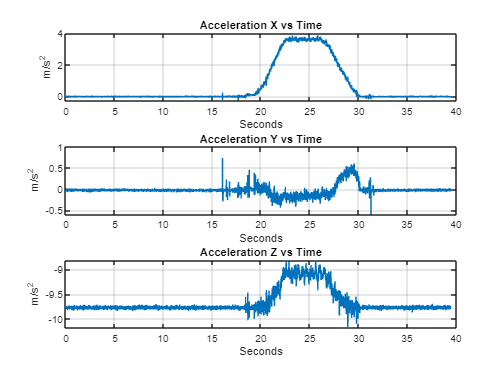

clf;

subplot(3,1,1);
plot(time, accel(:, 1));
title("Acceleration X vs Time")
xlabel("Seconds")
ylabel("m/s^2")
grid on;

subplot(3,1,2);
plot(time, accel(:, 2));
title("Acceleration Y vs Time")
xlabel("Seconds")
ylabel("m/s^2")
grid on;

subplot(3,1,3);
plot(time, accel(:, 3));
title("Acceleration Z vs Time")
xlabel("Seconds")
ylabel("m/s^2")
grid on;

Above we can see that the majority fo the acceleration happens within the x-axis and z-axis.  As this is a pitch up, this sense.

Below is the plots from the gyroscope in the sensor body range.

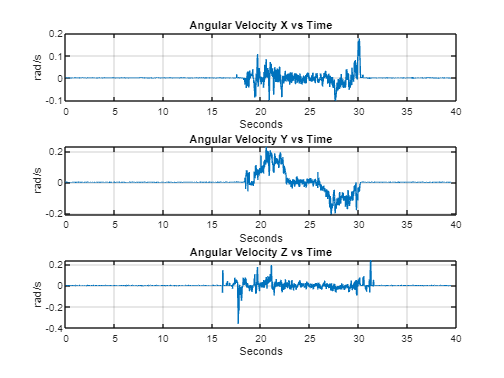

clf;

subplot(3,1,1);
plot(time, gyro(:, 1));
title("Angular Velocity X vs Time")
xlabel("Seconds")
ylabel("rad/s")
grid on;

subplot(3,1,2);
plot(time, gyro(:, 2));
title("Angular Velocity Y vs Time")
xlabel("Seconds")
ylabel("rad/s")
grid on;

subplot(3,1,3);
plot(time, gyro(:, 3));
title("Angular Velocity Z vs Time")
xlabel("Seconds")
ylabel("rad/s")
grid on;

Once again, we can see the pitch action, this time particular in the y-axis.  The pitch is then the area under the y-axis curve.

Below is the graph of the magnetometer from the sensor body frame.

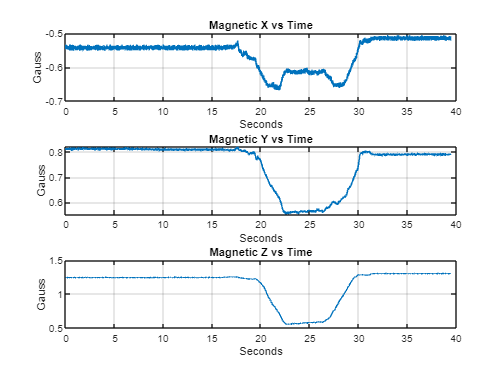

clf;

subplot(3,1,1);
plot(time, mag(:, 1));
title("Magnetic X vs Time")
xlabel("Seconds")
ylabel("Gauss")
grid on;

subplot(3,1,2);
plot(time, mag(:, 2));
title("Magnetic Y vs Time")
xlabel("Seconds")
ylabel("Gauss")
grid on;

subplot(3,1,3);
plot(time, mag(:, 3));
title("Magnetic Z vs Time")
xlabel("Seconds")
ylabel("Gauss")
grid on;

Again, we can see oberve the reduction of the magnetic field during the movement, as expected.